# Part(I) Modeling Tensile Stress-Strain Response of Mild Steel Reinforcement

## Question 1. Use the data and determine the Young’s modulus, the yield strength, the onset of strain hardening, the tensile strength, and the uniform strain

Using the data from the excel sheet the young's Young’s modulus $E_s$, the onset of strain hardening $\epsilon_{\textrm{sh}}$, the tensile strength $f_y$, and unform strain $\epsilon {\;}_{u\;}$.

### Part (i) Determining Yeidling Stress and Onset of Strain Hardening

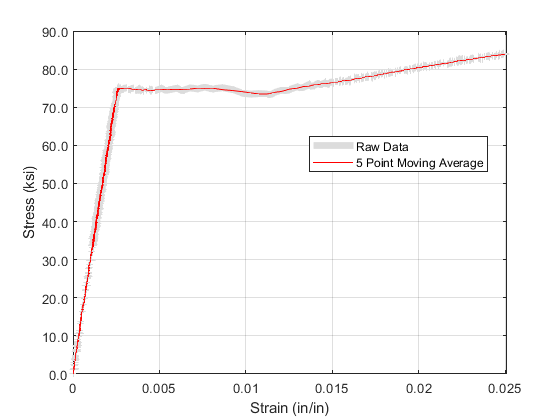

ans = 208.4306

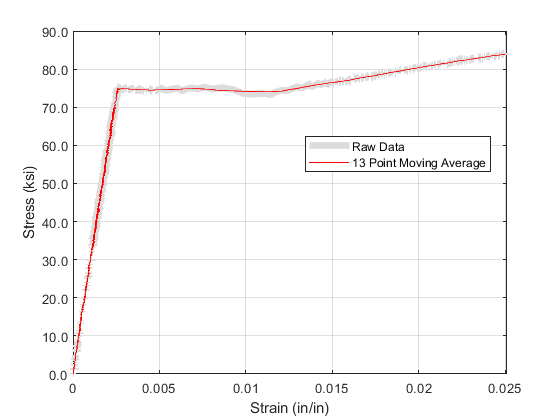

ans = 514.2298

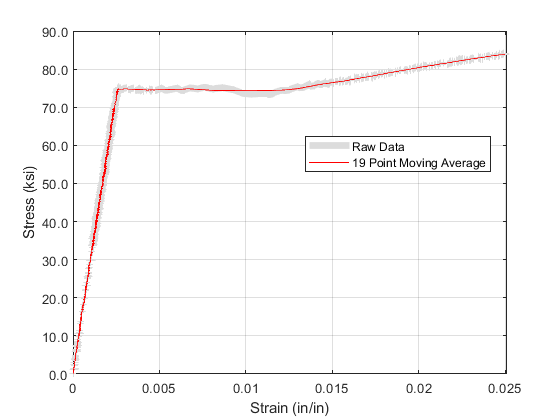

ans = 723.6548

close all;
strain_range = [0, 0.025]; % As specified 
[stress, strain] = get_data_for_range(strain_range); % Gets the data from the range

avg_values = [5, 13, 19]; % The number of samples that need to be taken for the moving average
for i = 1:length(avg_values) % Loops through the avg values
    figure(i); % Set up Figure
    mov_pt_avg = avg_values(i); % Sets the sampling size    
    plot_raw_data(strain, stress) % Plots raw data
    string(mov_pt_avg) + " Point Moving Average"; % Title of plot, just set as a temp variable
    plot(strain, movmean(stress,mov_pt_avg),'r','DisplayName',ans); % Filtered Data
%     print_figure(i) % Saves the figure as a pdf
    sum(sqrt((movmean(stress,mov_pt_avg) - stress).^2))
end

strain_range = [0, 0.13]; % As specified 
[stress, strain] = get_data_for_range(strain_range); % Gets the data from the range
close all;
plot_raw_data(strain, stress); hold on;% Raw Data
stress = movmean(stress,19);
idx_pts = findchangepts(stress,'Statistic','linear','MaxNumChanges',7); % Signal processing add-on
idx_pts(3) = idx_pts(3) + 100;
pts = plot(strain(idx_pts),stress(idx_pts),'x-b',"DisplayName",'Fitted Line'); hold on; % Fitted Line
plot_datatips(pts, strain, stress, idx_pts, (3:4)) % Using these two points
plot(strain, movmean(stress,19),'r','DisplayName','19 Point Moving Average'); % Filtered Data
xlim([0.001 0.02]); ylim([70 80]);

fy = min(stress(idx_pts(3):idx_pts(4))) % Finds the fy as the minimum stress in the yield plateau

fy = 74.3469

scatter(strain((stress == fy)),fy,'x',"DisplayName","Minimum Point");
e_sh = strain(idx_pts(4)) % Strain where strain hardening is consistent

e_sh = 0.0145

f_sh = stress(idx_pts(4)) % Stress where strain hardening is consistent

f_sh = 76.0996

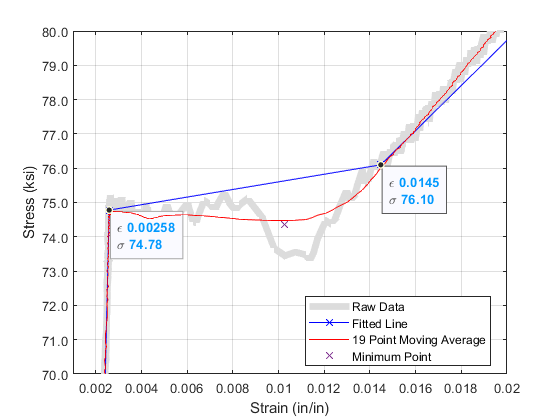

print_figure('3a') % Saves figure as PDF

Using the signal processing toolkit, I was able to segment the data in seven linear portions. From there, using the indices as located by the algorithm, the strains at the boundaries of the Lüders yeild plateau were found. The yeild stress was taken as the minimum stress between the two corresponding stresses.

### Part (ii) Determining Young's Modulus, $E_s$

strain_range = [0, 0.0025]; % As specified  
[stress, strain] = get_data_for_range(strain_range);% Gets the data from the range

close all;
[~, idx1] = min(abs(0.05*fy- stress)); % Finds the index where the stress is equal to 0.05*fy
[~, idx2] = min(abs(0.6*fy- stress)); % Finds the index where the stress is equal to 0.6*fy
range = (idx1:idx2); % The ids where the two strains are met
coefs = polyfit(strain(range),stress(range),1); % Use a linear fit to find best fit the data
Es = coefs(1) % Modulus is just the slope of this line

Es = 2.9076e+04

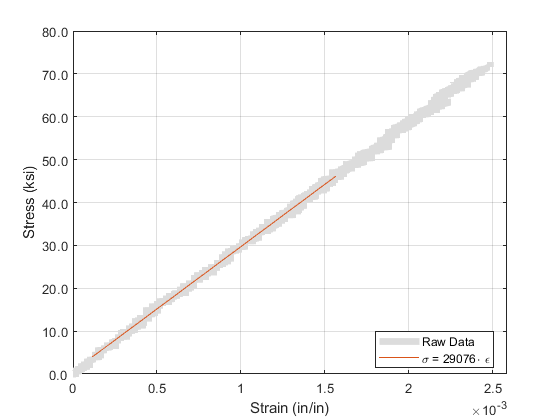

figure % Plot 
plot_raw_data(strain, stress); % Plots raw data from start to 0.025 strain
"\sigma = " + sprintf("%5.0f", coefs(1)) + "\cdot \epsilon"; % Text for the plot name- stored as temporary variable
plot(strain(range), polyval(coefs,strain(range)),'-',"DisplayName", ans); % Plots the fitted line between 0.05fy and 0.6fy
print_figure(4)

### Part (iii) Determine Ultimate Stress $f_{\textrm{su}}$ and Ultimate Strain $\epsilon_{\textrm{su}}$

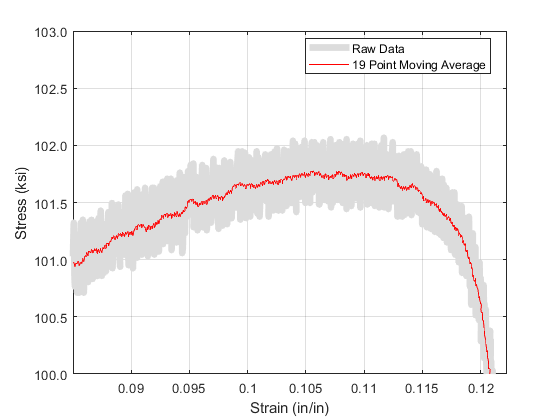

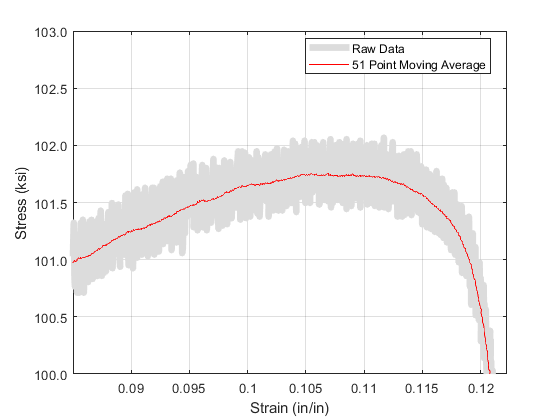

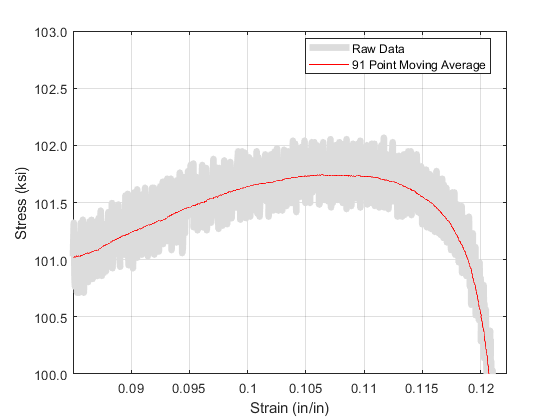

strain_range = [0.085, 0.125]; % As specified
[stress, strain] = get_data_for_range(strain_range); % Gets the data from the range

close all
avg_values = [19, 51, 91]; % The number of samples that need to be taken for the moving average
for i = 1:length(avg_values) % Loops through the avg values
    figure; % Set up figure, adjusted for figure numbers
    mov_pt_avg = avg_values(i); % Sets the sampling size    
    plot_raw_data(strain, stress) % Plots raw data
    int2str(mov_pt_avg) + " Point Moving Average"; % Title for plot- temporary variable
    plot(strain, movmean(stress,mov_pt_avg),'r','DisplayName',ans); % Filtered Data
    ylim([100,103]); % Per office hours
    print_figure(i+4) % Save figure as PDF
end

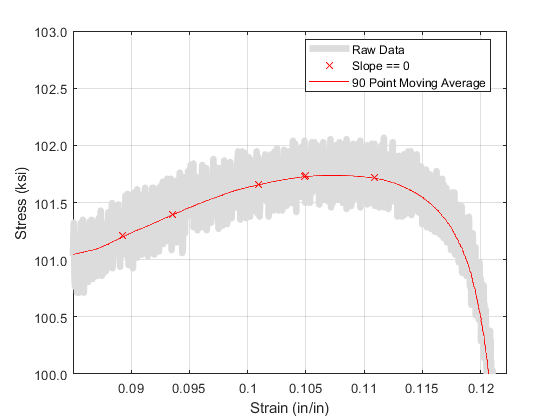

strain_range = [0.085, 0.125]; % As specified
[stress, strain] = get_data_for_range(strain_range); % Gets data

close all
plot_raw_data(strain, stress) % Plots raw data
mov_pt_avg = 90; % Arbritrary
stress = movmean(stress,mov_pt_avg); % Filtered by moving average
slopes = diff(stress) ./ diff(strain); % Finds the slope of at various points
slopes(isinf(slopes)) = 10^-10; % Remove the inf from data
pt = find(slopes == 0); % Finds where the plot has 0 slope
scatter(strain(pt),stress(pt),"Marker",'x',"MarkerEdgeColor","Red","DisplayName","Slope == 0"); % Plot thse points
string(mov_pt_avg) + " Point Moving Average"; % Title for plot- temporary variable
plot(strain, movmean(stress,mov_pt_avg),'r','DisplayName',ans); % Filtered Data
ylim([100,103]);
print_figure('7a')

e_su = mean(strain(pt(4:end-2))) % Start of the admissible range for strain

e_su = 0.1049

f_su = mean(stress(pt(4:end-2))) % Admissible Fsu

f_su = 101.7290

## Question 2. Fit a Tri-Linear Model to the Processed Data

Plot the complete stress strain relationship to point $\left.{\left(\epsilon \right.}_{\textrm{su}} ,f_{\textrm{su}} \right)$.

Compare the model and the processed data and show the value computed for the hardening ratio r. 

strain_range = [0, e_su]; % As specified 
[stress, strain] = get_data_for_range(strain_range); % Get data for range

close all
plot_raw_data(strain, stress) % Plot raw data
zeta = 0.55; % As specifiec
e_y = fy/Es; 
strain_pt = [0, e_y, zeta*e_su, e_su]; % As specifiec
stress_pt = [0, fy, f_su, f_su]; % As specifiec
plot(strain_pt,stress_pt,"DisplayName","Trilinear Model") % Plot
r = (f_su/fy - 1) / (zeta*e_su/e_y - 1) % Strain hardening example

r = 0.0171

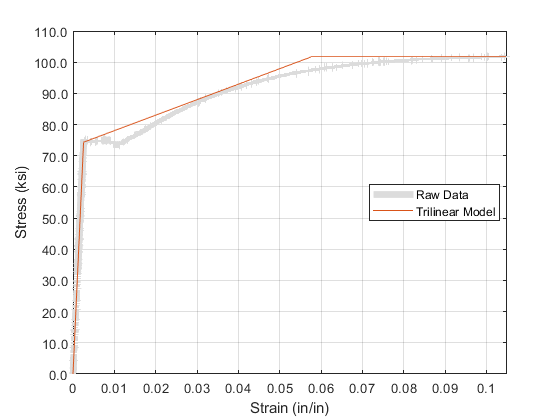

print_figure(8)

## Question 3. Fit the Data to the Modified Mander's Model

Determine the power factor, P>1, through a least square error minimization procedure.

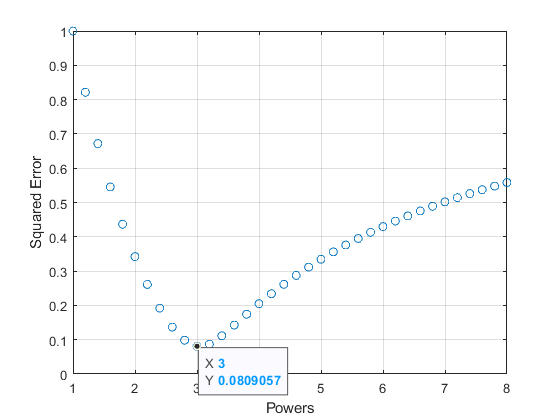

strain_range = [e_sh, e_su]; % Data range is from 0 to esu
[stress, strain] = get_data_for_range(strain_range);  % Get data

stress = movmean(stress, 91); % Assumed stress values; Varying this did not affect the P 

P_trials = 1:0.2:8; % Selected powers for trial 
sq_error = zeros(1,length(P_trials)); % Initialized sq erorr for results
i = 1; % Double loop counter- limitation of MATLAB (I'm joking)
for P = P_trials
    stress_guess = f_su - (f_su -fy) * ((e_su - strain)/(e_su- e_sh)).^P; % Generates the stress 
    sq_error(i) = sum(sqrt((stress - stress_guess).^2)); % Calculates the sq. error
    i = i+1; % counter ++
end
sq_error = sq_error./max(sq_error);
P = P_trials(sq_error == min(sq_error));
close all;
plt = scatter(P_trials, sq_error); % As needed
datatip(plt,'DataIndex',find(sq_error == min(sq_error)),"Location","southeast"); % Min Point
xlabel("Powers"); ylabel("Squared Error");box on, grid on; 
print_figure(9)

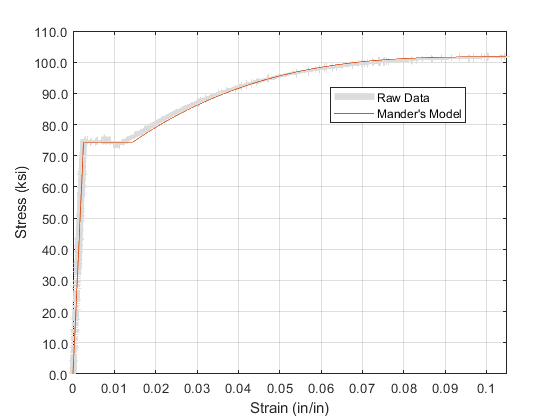

[model_stress, model_strain] = deal(linspace(0,e_su,1000)); % Initialize model strain range
i = 1;  % Double loop counter- limitation of MATLAB (I'm joking)
for epsilon = model_strain
    if epsilon <= e_sh % If the strain is before the start of the strain hardending
      model_stress(i) = min(fy, Es*epsilon); % Linear Function
      i = i+1;  % counter ++
    elseif epsilon >= e_sh && epsilon <= e_su % Else use the power function
      model_stress(i) = f_su - (f_su -fy) * ((e_su - epsilon)/(e_su- e_sh)).^P; % Mander's Model
      i = i+1; % counter ++
    end
end

close all
strain_range = [0, e_su]; % Data range
[stress, strain] = get_data_for_range(strain_range); % Get Data 
plot_raw_data(strain, stress) % Plot
plot(model_strain, model_stress,"DisplayName","Mander's Model"); % Model data
print_figure(10)

## Functions

function plot_datatips(pts, strain,stress,idx,range)
    % For that one figure ... spent too much time on this one
    pts.DataTipTemplate.Interpreter = 'tex';
    pts.DataTipTemplate.DataTipRows(1).Format = '%0.3g';
    pts.DataTipTemplate.DataTipRows(1).Label = '\epsilon';
    pts.DataTipTemplate.DataTipRows(2).Format = '%.2f';
    pts.DataTipTemplate.DataTipRows(2).Label = '\sigma';
    for pt = idx(range)'
        datatip(pts,strain(pt),stress(pt),"location","southeast");
    end
end

function [stress, strain] = get_data_for_range(range_)
    % Import the data but also cuts it into the range that I need
    opts = spreadsheetImportOptions("NumVariables", 4);
    opts.Sheet = "Data 2021";
    opts.DataRange = "A7:D5116";
    opts.VariableNames = ["Var1", "Stress", "Var3", "Strain"];
    opts.SelectedVariableNames = ["Stress", "Strain"];
    opts.VariableTypes = ["char", "double", "char", "double"];
    opts = setvaropts(opts, ["Var1", "Var3"], "WhitespaceRule", "preserve");
    opts = setvaropts(opts, ["Var1", "Var3"], "EmptyFieldRule", "auto");
    file = "C:\Users\Louis Lin\Workspace\Academic\UCSD\SE 211\Homework\HW 1\data\No 11 Bar Tensile Test 2021.xlsx";
    No11BarTensileTest2021 = readtable(file, opts, "UseExcel", false);
    
    % For the range I need
    stress = No11BarTensileTest2021.Stress; % Saves the stress data
    strain = No11BarTensileTest2021.Strain; % Saves the strain data
    strain_range = and(strain >= range_(1), strain<=range_(2)); % Selects a data range as specified
    stress = stress(strain_range); 
    strain = strain(strain_range);
end

function plot_raw_data(strain, stress)
    % Formats the raw data plot consistently
    hold on; grid on; box on; % Per choice
    ylabel("Stress (ksi)"); xlabel("Strain (in/in)"); ytickformat('%.1f');
    axis([max(0,min(strain)),max(strain)+0.0001,max(0,round(min(stress),-1)-10),round(max(stress),-1)+10]) % Per choice
    raw_data = plot(strain,stress,"Color",[220,220,220]/255,'LineWidth', 5,'DisplayName',"Raw Data"); 
    raw_data.Color(4) = 0.3;% Raw Data alpha
    legend('Location',"best","Interpreter","tex");
end

function print_figure(no)
    % Saves the figures in a consistent manner
    orient(gcf,'landscape');
    folder = '..\figures\';
    name = 'Figure' +string(no);
    print(folder+name,'-dpdf','-fillpage','-PMicrosoft Print to PDF','-r600','-painters')
end